# 15.16 - General Numeric Solution

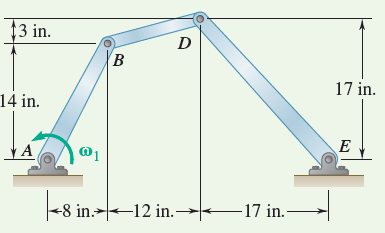

## Given                                          Find


$$\theta_A =f\left(t\right)\;$$
                                                         
$$\theta_B ,{\;\theta }_E ,\omega_B ,\omega_E ,\alpha_B ,\alpha_E$$


## Initialize variables and known quantities

dt = 0.01;
t = 0:dt:2*pi; % time vector from 0 to 10 in steps of dt

rAB = [8 14]

rAB =      8    14


rBD = [12 3]

rBD =     12     3


rED = [-17 17]

rED =    -17    17


thetaA0 = atan(rAB(2) / rAB(1)) % initial value for thetaA

thetaA0 = 1.0517

thetaB0 = atan(rBD(2) / rBD(1)) % initial value for thetaB

thetaB0 = 0.2450

thetaE0 = atan(rED(2) / -rED(1)) % initial value for thetaE

thetaE0 = 0.7854


thetaA = thetaA0 + sin(t)

thetaA =     1.0517    1.0617    1.0716    1.0816    1.0916    1.1016    1.1116    1.1216    1.1316    1.1415    1.1515    1.1614    1.1714    1.1813    1.1912    1.2011    1.2110    1.2208    1.2307    1.2405    1.2503    1.2601    1.2699    1.2796    1.2894    1.2991    1.3087    1.3184    1.3280    1.3376    1.3472    1.3567    1.3662    1.3757    1.3851    1.3945    1.4039    1.4133    1.4226    1.4318    1.4411    1.4503    1.4594    1.4685    1.4776    1.4866    1.4956    1.5045    1.5134    1.5223


omegaA = cos(t)

omegaA =     1.0000    1.0000    0.9998    0.9996    0.9992    0.9988    0.9982    0.9976    0.9968    0.9960    0.9950    0.9940    0.9928    0.9916    0.9902    0.9888    0.9872    0.9856    0.9838    0.9820    0.9801    0.9780    0.9759    0.9737    0.9713    0.9689    0.9664    0.9638    0.9611    0.9582    0.9553    0.9523    0.9492    0.9460    0.9428    0.9394    0.9359    0.9323    0.9287    0.9249    0.9211    0.9171    0.9131    0.9090    0.9048    0.9004    0.8961    0.8916    0.8870    0.8823


alphaA = -sin(t)

alphaA =          0   -0.0100   -0.0200   -0.0300   -0.0400   -0.0500   -0.0600   -0.0699   -0.0799   -0.0899   -0.0998   -0.1098   -0.1197   -0.1296   -0.1395   -0.1494   -0.1593   -0.1692   -0.1790   -0.1889   -0.1987   -0.2085   -0.2182   -0.2280   -0.2377   -0.2474   -0.2571   -0.2667   -0.2764   -0.2860   -0.2955   -0.3051   -0.3146   -0.3240   -0.3335   -0.3429   -0.3523   -0.3616   -0.3709   -0.3802   -0.3894   -0.3986   -0.4078   -0.4169   -0.4259   -0.4350   -0.4439   -0.4529   -0.4618   -0.4706



thetaB = zeros(1, length(t)); % zero vector of length t
omegaB = thetaB; % shortcut to assign it a zero vector
alphaB = thetaB;

thetaE = thetaB;
omegaE = thetaB;
alphaE = thetaB;

% add in initial values
thetaB(1) = thetaB0

thetaB =     0.2450         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


thetaE(1) = thetaE0

thetaE =     0.7854         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


## Analyze System for Missing Initial Values

We need to find: $\omega_{B_0 } ,\alpha_{B_0 } ,\omega_{E_0 } ,\alpha_{E_0 }$

sympref('FloatingPointOutput',true); % symbolic math setting
wb0 = sym('wb0'); % denotes 'wb0' as a symbolic variable
ab0 = sym('ab0');
we0 = sym('we0');
ae0 = sym('ae0');

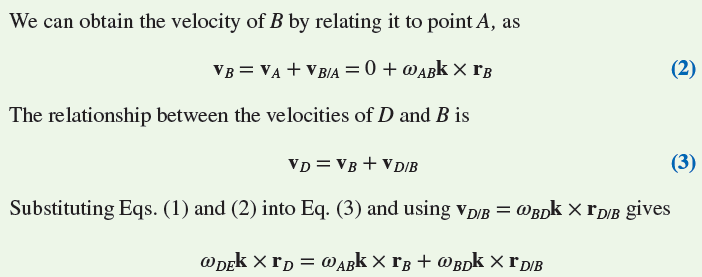

k = [0 0 1];
lhs = cross(we0*k, [rED 0])

$$lhs = \left(\begin{array}{ccc} -17\,{\mathrm{we}}_{0} & -17\,{\mathrm{we}}_{0} & 0 \end{array}\right)$$

rhs = cross(omegaA(1)*k, [rAB 0]) + cross(wb0*k, [rBD 0])

$$rhs = \left(\begin{array}{ccc} -3\,{\mathrm{wb}}_{0}-14 & 12\,{\mathrm{wb}}_{0}+8 & 0 \end{array}\right)$$

S = solve(lhs==rhs)

S = struct with fields:
    wb0: [1×1 sym]
    we0: [1×1 sym]


S.wb0

$$ans = -1.4667$$

S.we0

$$ans = 0.5647$$


% set first values in arrays to initial value
omegaB(1) = double(S.wb0)

omegaB =    -1.4667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


omegaE(1) = double(S.we0)

omegaE =     0.5647         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Evaluate each term of the accleration equation separately

lhs = cross(ae0*k, [rED 0]) - omegaE(1)^2 * [rED 0]

$$lhs = \left(\begin{array}{ccc} 5.4211-17\,{\mathrm{ae}}_{0} & -17\,{\mathrm{ae}}_{0}-5.4211 & 0 \end{array}\right)$$

ab = cross(alphaA(1)*k, [rAB 0]) - omegaA(1)^2 * [rAB 0]

ab =     -8   -14     0


adb = cross(ab0*k,[rBD 0]) - omegaB(1)^2 * [rBD 0]

$$adb = \left(\begin{array}{ccc} -3\,{\mathrm{ab}}_{0}-25.8145 & 12\,{\mathrm{ab}}_{0}-6.4536 & 0 \end{array}\right)$$

combine for RHS and solve

rhs = ab + adb

$$rhs = \left(\begin{array}{ccc} -3\,{\mathrm{ab}}_{0}-33.8145 & 12\,{\mathrm{ab}}_{0}-20.4536 & 0 \end{array}\right)$$


S = solve(lhs == rhs)

S = struct with fields:
    ab0: [1×1 sym]
    ae0: [1×1 sym]


alphaB(1) = double(S.ab0)

alphaB =    -1.6135         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


alphaE(1) = double(S.ae0)

alphaE =     2.0232         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


We now have all initial values for the system!

## Simulate Stepping Through Time

At each time step $t_i$:

- calculate $\omega_i =\omega_{i-1} +\alpha_{i-1} \textrm{dt}$

- calculate $\theta_i =\theta_{i-1} +\omega_{i-1} \textrm{dt}+\frac{1}{2}\alpha_{i-1} {\textrm{dt}}^2$

- calculate $\alpha_i \;$using the above system of equations

- update rAB, rBD, rED

lrAB = norm(rAB); % get the length of rAB
lrBD = norm(rBD);
lrED = norm(rED);

for i = 2:length(t) % already have initial values, so start at second time step
    
    %update omegas
    omegaB(i) = omegaB(i-1) + alphaB(i-1)*dt;
    omegaE(i) = omegaE(i-1) + alphaE(i-1)*dt;
    
    %update thetas
    thetaB(i) = thetaB(i-1) + omegaB(i-1)*dt + 0.5*alphaB(i-1)*dt^2;
    thetaE(i) = thetaE(i-1) + omegaE(i-1)*dt + 0.5*alphaE(i-1)*dt^2;
    
    %update rAB, rBD, rED
     rAB = [lrAB*cos(thetaA(i)), lrAB*sin(thetaA(i))];
     rBD = [lrBD*cos(thetaB(i)), lrBD*sin(thetaB(i))];
     rED = [-lrED*cos(thetaE(i)), lrED*sin(thetaE(i))];
     
    %update alphas using system of equations
    lhs = cross(ae0*k, [rED 0]) - omegaE(1)^2 * [rED 0];
    ab = cross(alphaA(1)*k, [rAB 0]) - omegaA(1)^2 * [rAB 0];
    adb = cross(ab0*k,[rBD 0]) - omegaB(1)^2 * [rBD 0];
    rhs = ab + adb;
    S = solve(lhs == rhs);
    alphaB(i) = double(S.ab0);
    alphaE(i) = double(S.ae0);
end